## Problem 2

Consider the mesh called `meshEscaire2foratsTirang`. Let  $p_{0} = (-1.4,3.4)$ and assign the following *distance value* to each node $v:$


$$$$
f(v) = \| v - p_{0}\|,
$$$$


that is, $f(v)$ is the distance from $v$ to $p_{0}$.

**Hint:** In Matlab, the distance from $v$ to $p_{0}$ is computed with `norm(v - p0)`.

(a) (2points) The farthest (most distant) node from $p_{0}$ is node number:

- `85`

- `84`

- `82 ✔️`

- `81`

- `83`

- Empty answer (no penalty)

**Hint:** The command `[M,I] = max(A)` returns the maximum element `M` and its index `I`.

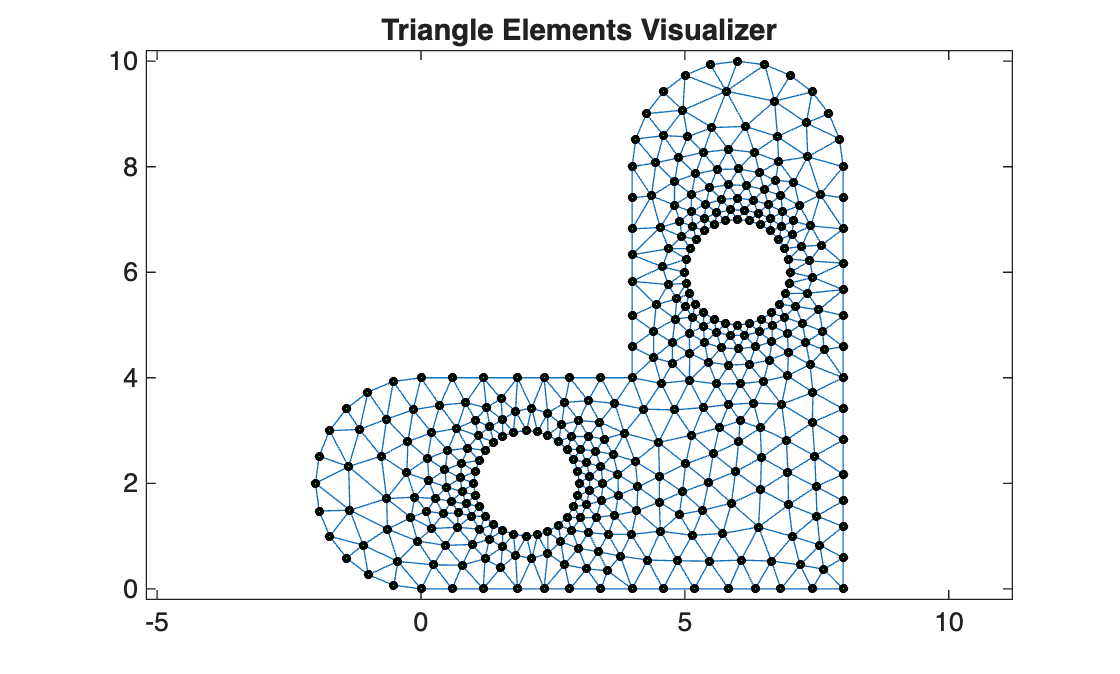


clearvars
close all

load meshEscaire2foratsTriang elem nodes

%Item (a)
p0 = [-1.4, 3.4];
numNodes = size(nodes,1);
numElem = size(elem,1);

plotElementsOld(nodes,elem,0)

We use the function `vecnorm` to find the norm of the difference $p_{0} - \mathtt{nodes}_{i}$ for each row, $i = 1\div\mathtt{numnodes}$of matrix $\mathtt{nodes}$. 

help vecnorm

 vecnorm - Vector-wise norm

    Syntax
      N = vecnorm(A)
      N = vecnorm(A,p)
      N = vecnorm(A,p,dim)

    Input Arguments
      A - Input array
        vector | matrix | multidimensional array
      p - Norm type
        2 (default) | positive scalar | Inf
      dim - Dimension to operate along
        positive integer scalar

    Examples
      1-Norm and 2-Norm of Vector
      2-Norm of Matrix Columns

    See also norm, 

%f = @(v) sqrt((v(:,1)-p0(1)).^2+ (v(:,2)-p0(2)).^2);
%f = @(v) sqrt(sum((p0 - v).^2,2))

f = @(v) vecnorm(p0-v,2,2); % help vecnorm to see how this function works
[distanceFarthestNode, farthestNode] = max(f(nodes));
fprintf("Question (a)\n" + ...
    "The farthest node from p0 is node number: %d", farthestNode);

Question (a)
The farthest node from p0 is node number: 82

(b) (4 points) Interpolate the function $f$ at the point $p = (5.1, 2.9)$. The interpolated value is:

- `6.4478e+00`

- `6.5848e+00`

- `6.5196e+00 ✔️`

- `6.4413e+00`

- Empty answer (no penalty)

%Item (b)
p = [5.1, 2.9];

for e = 1:numElem
    vertexs = nodes(elem(e,:),:);
    [alphas, isInside]=baryCoord(vertexs, p);
    if isInside
        containingElement = e;
        barycentricCoordinates = alphas;
        break
    end
end

interpValueOffAtp = barycentricCoordinates * f(vertexs);
fprintf("Question (b)\n" + ...
    "Interpolated value of f at point (%.1f, %.1f): %.4e", p',interpValueOffAtp);

Question (b)
Interpolated value of f at point (5.1, 2.9): 6.5196e+00

(c) (2 points) Given a triangular element, its barycenter $g$ has barycentric coordinates $(1/3, 1/3, 1/3)$. Find the barycenter of the element number $7$ in the mesh:

- `(4.6400e+00, 6.2143e-01)`

- Empty answer (no penalty)

- `(4.5369e+00, 6.0762e-01)`

- `(5.6196e+00, 7.5262e-01)`

- `(5.1556e+00, 6.9048e-01) ✔️`

%Item (c)
%vertexs element e = 7
e = 7;
vertexs = nodes(elem(e,:),:);
barycenterOfp = [1/3, 1/3, 1/3] * vertexs;
fprintf("Question (c)\n" + ...
    "Coordinates of the barycenter of the element e = %d: (%.4e, %.4e)",...
    e,barycenterOfp');

Question (c)
Coordinates of the barycenter of the element e = 7: (5.1556e+00, 6.9048e-01)

(d) (2 points) Given a triangular element with barycenter $g$, define its *interpolation error* as the difference between the interpolated value of $f$ at $g$. The interpolation error for element number $7$ in the mesh is:

- [`4.0937e-03`

- [`4.0568e-03`

- `Empty` answer (no penalty)

- `3.6880e-03 ✔️`

- `3.9831e-03`

%Item (d)
interpf = [1/3, 1/3, 1/3] * f(vertexs);
valuef = f(barycenterOfp);
err = abs(valuef-interpf);
fprintf("Question (d) Error: %.4e\n", err)

Question (d) Error: 3.6880e-03
